clc;
clear;
close all;

%% Define plant transfer function
num = [1];
den = [1 3 2];
G = tf(num, den);

disp('Plant Transfer Function:')

Plant Transfer Function:


G


G =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.


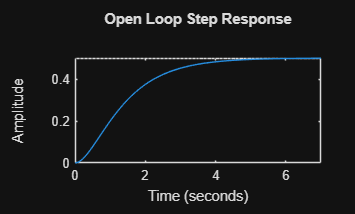


%% Open loop response
figure;
step(G);
title('Open Loop Step Response');

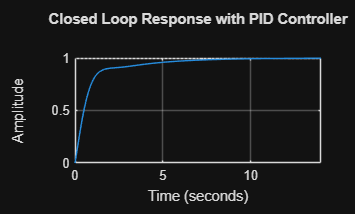


%% ------------------------------
%% PID Controller Design
%% ------------------------------

Kp = 5;
Ki = 2;
Kd = 1;

C_pid = pid(Kp,Ki,Kd);

% Closed loop system
T_pid = feedback(C_pid*G,1);

figure;
step(T_pid);
title('Closed Loop Response with PID Controller');
grid on;

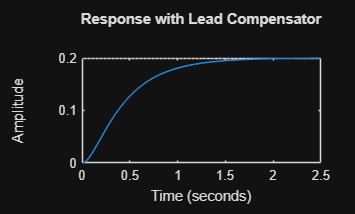


%% ------------------------------
%% Lead Compensator
%% ------------------------------

z = 1;
p = 10;
K = 5;

C_lead = K*tf([1 z],[1 p]);

T_lead = feedback(C_lead*G,1);

figure;
step(T_lead);
title('Response with Lead Compensator');

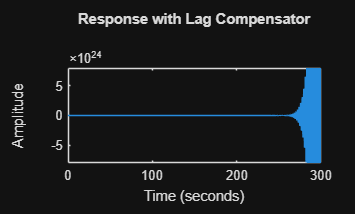


%% ------------------------------
%% Lag Compensator
%% ------------------------------

z = 10;
p = 1;
K = 5;

C_lag = K*tf([1 z],[1 p]);

T_lag = feedback(C_lag*G,1);

figure;
step(T_lag);
title('Response with Lag Compensator');

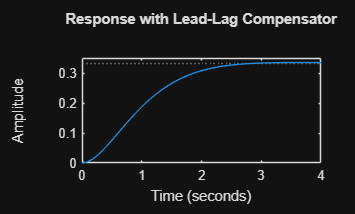


%% ------------------------------
%% Lead-Lag Compensator
%% ------------------------------

z1 = 1;
p1 = 10;
z2 = 10;
p2 = 1;

C_leadlag = tf(conv([1 z1],[1 z2]),conv([1 p1],[1 p2]));

T_leadlag = feedback(C_leadlag*G,1);

figure;
step(T_leadlag);
title('Response with Lead-Lag Compensator');

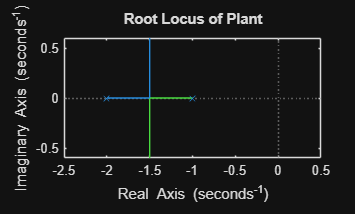


%% Root Locus
figure;
rlocus(G);
title('Root Locus of Plant');

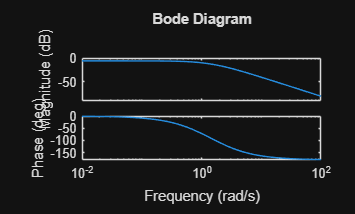


%% Bode Plot
figure;
bode(G);

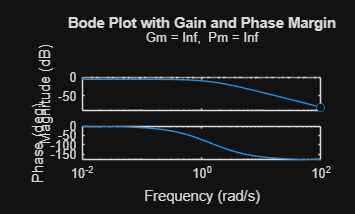

margin(G);
title('Bode Plot with Gain and Phase Margin');